初期状態の値(initial_generator_state)と状態定常値の差に関して、定常値に収束するための初期値誤差を調べ、その境界を探索する 

状態における誤差は　10^left　10^right  とおく  ( 例、left = -17 のとき 10^-17 ) 

( left: 最終状態値と状態定常値との差がゼロであるべき指数,  right: 最終状態値と状態定常値との差がゼロではない指数 )

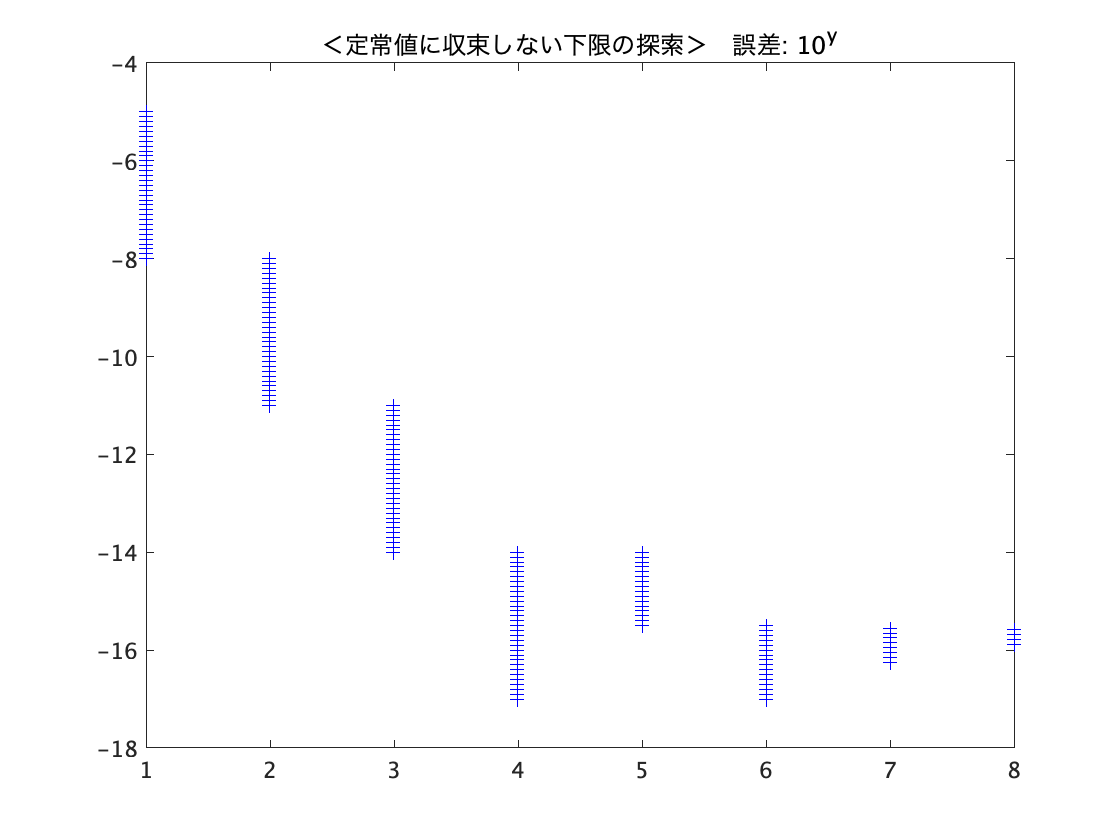

ans = 3

ans =     -8    -5


ans = 0.0102

error_left = 	1.0e+-3 *

    0.1327   -0.0144   -0.0017
   -0.4847    0.0527   -0.0054
    0.3258   -0.0356   -0.0073


error_right = 	1.0e+-3 *

    0.1764    0.0057   -0.0035
   -0.5990   -0.0205   -0.0025
    0.4201    0.0137   -0.0019


ans = 3

ans =    -11    -8


ans = 5.9900e-04

error_left = 	1.0e+-3 *

   -0.0366   -0.0223   -0.0010
    0.1340    0.0813   -0.0065
   -0.0906   -0.0546   -0.0094


error_right = 	1.0e+-3 *

    0.1327   -0.0144   -0.0017
   -0.4847    0.0527   -0.0054
    0.3258   -0.0356   -0.0073


ans = 3

ans =    -14   -11


ans = 4.8468e-04

error_left = 	1.0e+-3 *

   -0.1708   -0.0031   -0.0028
    0.6232    0.0112   -0.0037
   -0.4190   -0.0075   -0.0042


error_right = 	1.0e+-3 *

   -0.0366   -0.0223   -0.0010
    0.1340    0.0813   -0.0065
   -0.0906   -0.0546   -0.0094


ans = 3

ans =    -17   -14


ans = 1.3402e-04

error_left =      0     0     0
     0     0     0
     0     0     0


error_right = 	1.0e+-3 *

   -0.1708   -0.0031   -0.0028
    0.6232    0.0112   -0.0037
   -0.4190   -0.0075   -0.0042


ans =   -15.5000  -14.0000


ans = 6.2317e-04

error_left = 	1.0e+-3 *

   -0.0705    0.0208   -0.0049
    0.2551   -0.0760   -0.0003
   -0.1707    0.0511    0.0023


error_right = 	1.0e+-3 *

   -0.1708   -0.0031   -0.0028
    0.6232    0.0112   -0.0037
   -0.4190   -0.0075   -0.0042


ans = 3

ans =   -17.0000  -15.5000


ans = 6.2317e-04

error_left =      0     0     0
     0     0     0
     0     0     0


error_right = 	1.0e+-3 *

   -0.0705    0.0208   -0.0049
    0.2551   -0.0760   -0.0003
   -0.1707    0.0511    0.0023


ans =   -16.2500  -15.5000


ans = 2.5509e-04

error_left =      0     0     0
     0     0     0
     0     0     0


error_right = 	1.0e+-3 *

   -0.0705    0.0208   -0.0049
    0.2551   -0.0760   -0.0003
   -0.1707    0.0511    0.0023


ans =   -15.8750  -15.5000


ans = 2.5509e-04

error_left = 	1.0e+-15 *

    0.2220         0         0
    0.2220         0         0
    0.2220         0         0


error_right = 	1.0e+-3 *

   -0.0705    0.0208   -0.0049
    0.2551   -0.0760   -0.0003
   -0.1707    0.0511    0.0023


clear
left = -5;
right = -2;

tspan = [0 100];

%定常値を設定
steady_delta = [1.1;1.2;1.4];
steady_deltaomega = [0;0;0];
steady_E = [4;5;3];
steady_generator_state = [steady_delta; steady_deltaomega; steady_E];



%最終時間における状態値と状態定常値の差を得る
get_final_error_wrap = @(cnt) get_final_error(cnt,tspan, steady_generator_state);

error_left = get_final_error_wrap(left);
error_right = get_final_error_wrap(right);

t = 1;
f1 = figure;
f2 = figure;

% max(abs(error_right(:))) > ?????　でどれだけの誤差まで許容するかを設定（max(初期値)<1なら0.000001程度、max(初期値)>1なら1）
% t < ???? で最高何回探索するかを設定
while (max(abs(error_right(:))) > 0.00001 | all(error_right(:) == 0) ) & t < 30
    
    if all(error_left(:) == 0) & any(error_right(:) ~= 0)
        
        %1
        if (right - left) < 0.001
            error_left(:)
            4
            break
        end
        
        left = (right + left) /2;
        

        
    elseif  all(error_right(:) == 0)
        
        %2
        
        temp = left;
        
        left = right;
        
        right = right + (right - temp);
        
    elseif any(error_left(:) ~= 0)
        
        if max(abs(error_left(:))) < 0.00001
            break
        end
        
        3
        
        temp = right;
        
        right = left;
        
        left = left - (temp - left);
      
    end
    [left, right]
    max(abs(error_right(:)))
    figure(f1);
    plot(t,left:0.1:right,'b+')
    title('＜定常値に収束しない下限の探索＞　誤差: 10^y')
    hold on
    
    if max(abs(error_right(:))) > 0
        figure(f2);
        plot(t,max(abs(error_right(:))),'r*')
        title('定常値との最大誤差の絶対値')
        hold on
    end
    
    t = t + 1;
    
    error_left = get_final_error_wrap(left)
    error_right = get_final_error_wrap(right)
 
end

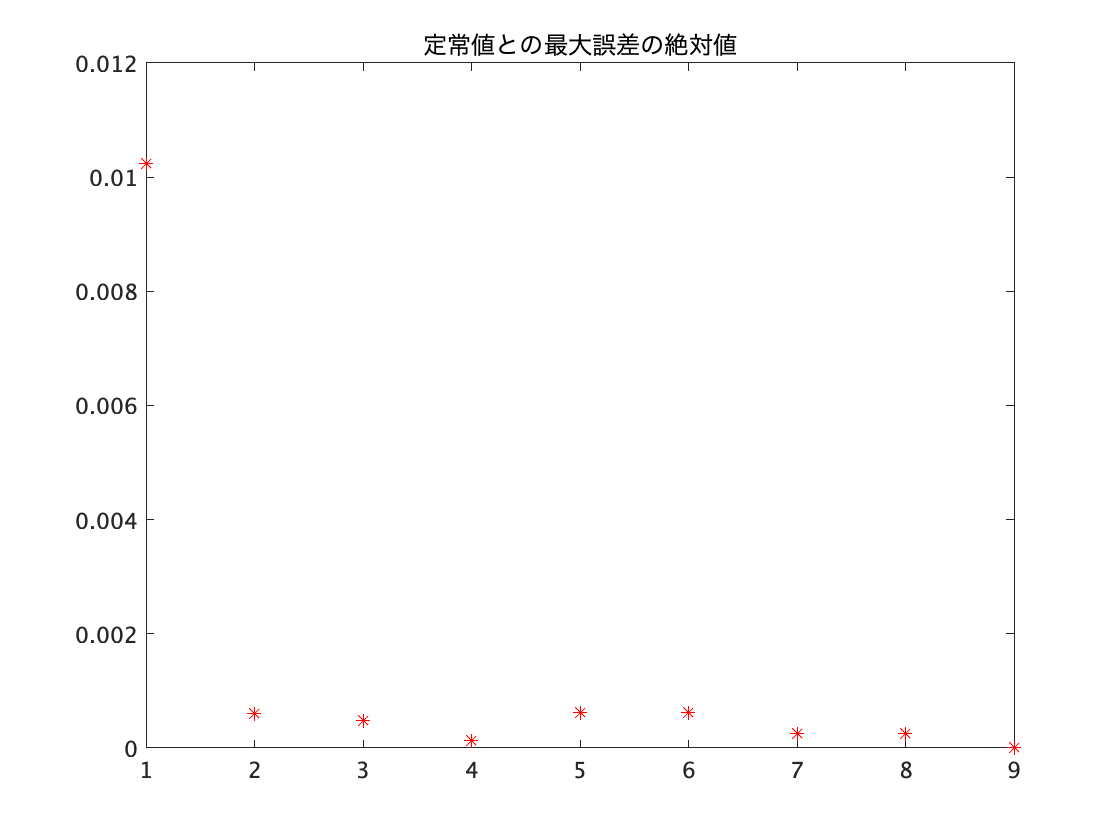

figure(f2);
plot(t,max(abs(error_left(:))),'r*')
hold off

right

right = -15.5000

left

left = -15.8750

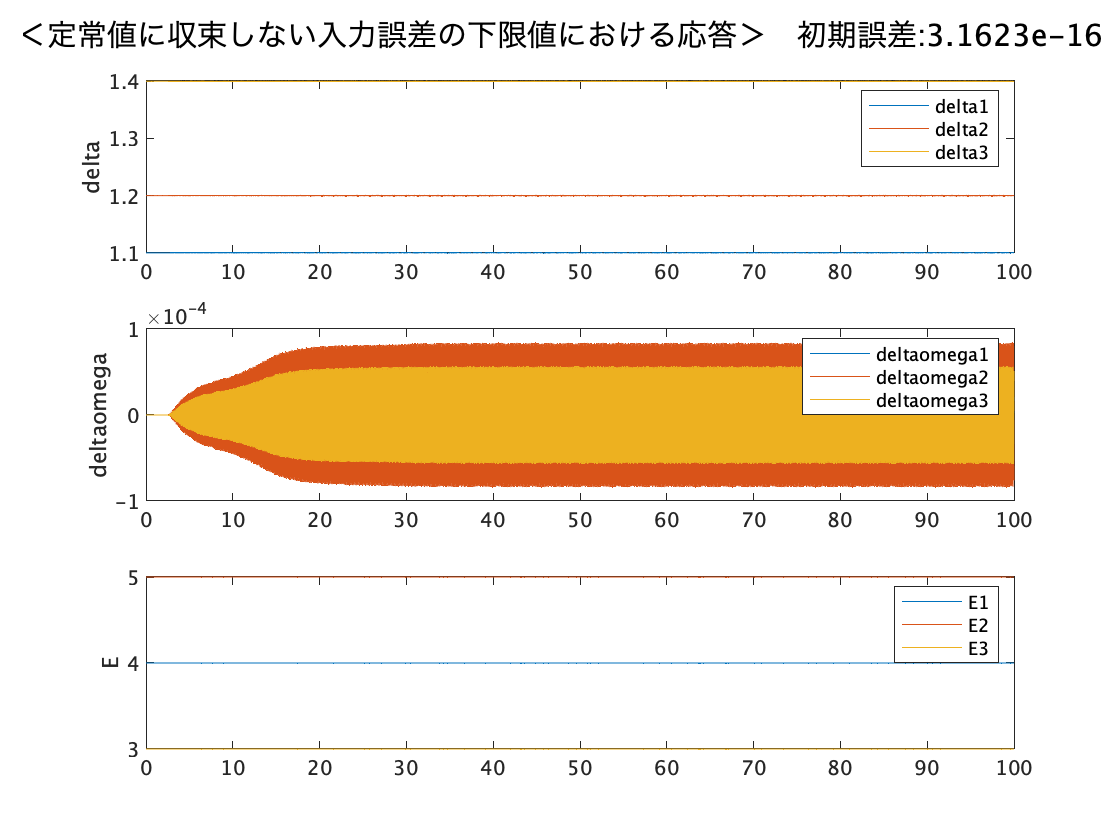

figure;
plot_generator_state(right,tspan,steady_generator_state)
sgtitle(['＜定常値に収束しない入力誤差の下限値における応答＞　初期誤差:',num2str(10^right)])

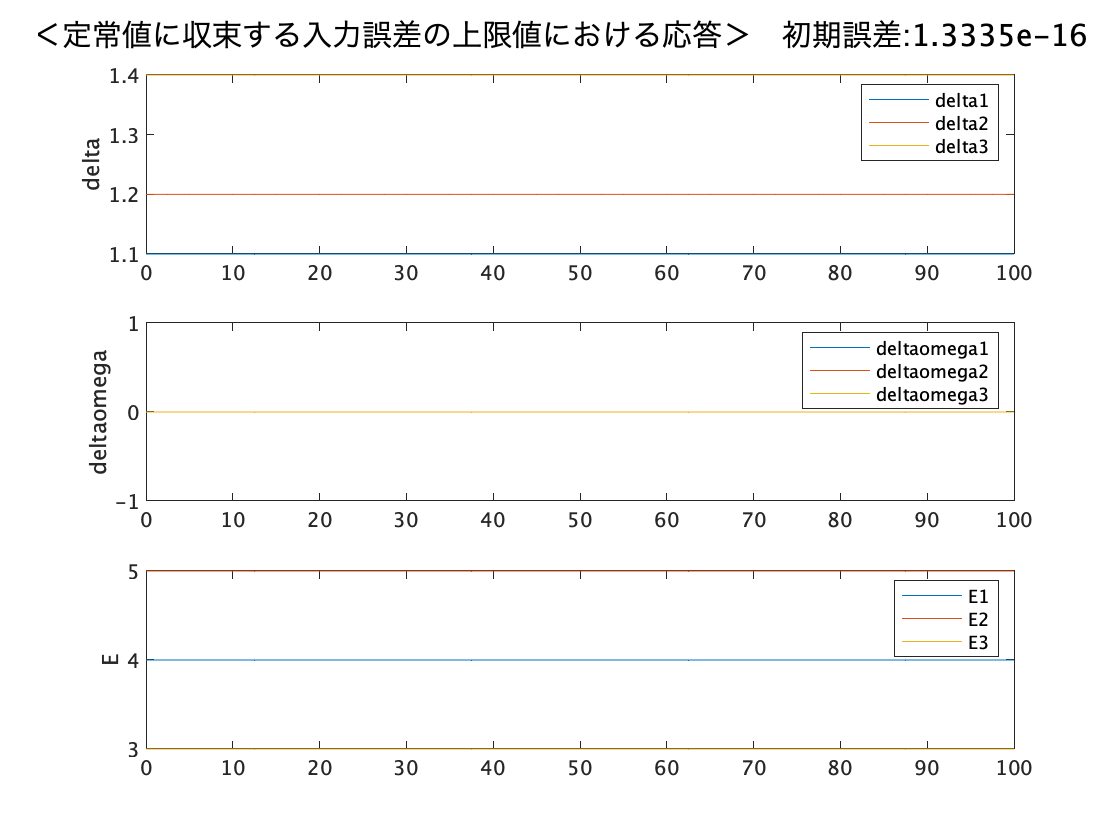

figure;
plot_generator_state(left,tspan,steady_generator_state)
sgtitle(['＜定常値に収束する入力誤差の上限値における応答＞　初期誤差:',num2str(10^left)])